# **TASK 1)**

# Part a)

clear; % Clear workspace

N = 100; % Ex. number of samples

theta_true = [0; 0]; % True parameters as per Appendix A
sigma2 = 1; % Variance of the errors -> normally distr. with mean zero

% dataset
X = [ones(N, 1), (1 + (-1).^(1:N))']; % Design matrix
e = randn(N, 1) * sqrt(sigma2); % Errors
y = e; % Outputs as per Appendix A, y_i = e_i since theta_true = [0; 0]

% Estimating parameters using the LinRegress function
m = LinRegress(X, y);

% Est. variance - 1ST param
estimated_variance = m.variance(1, 1);

% Theoretical variance (Appendix A)
theoretical_variance = sigma2 / N; 

fprintf('True parameters: %f\n', theta_true);

True parameters: 0.000000
True parameters: 0.000000


fprintf('Estimated parameter: %f\n', m.theta);

Estimated parameter: -0.052306
Estimated parameter: -0.129399


fprintf('Estimated variance for the first parameter: %f\n', estimated_variance);

Estimated variance for the first parameter: 0.018579


fprintf('Theoretical variance for the first parameter: %f\n', theoretical_variance);

Theoretical variance for the first parameter: 0.010000


# Part b)                                                                             *****Testing The Function*****

% testing evalmodel and linregress
X_example = [ones(10, 1), (1:10)']; % 10 samples with linear trend -> has intercept
theta_example = [1; 2]; % true params   
y_example = X_example * theta_example + randn(10, 1) * 0.5; % Generating example outputs with some noise

% LinRegress to estimate the model parameters from the example data
model_estimated = LinRegress(X_example, y_example);

% Using/testing evalModel to predict outputs based on the estimated model and a new set of regressors
X_new = [ones(5, 1), (11:15)']; % New regressor values for prediction
y_pred = evalModel(model_estimated, X_new);

disp('Predicted outputs:');

Predicted outputs:


disp(y_pred);

   22.9480
   24.9920
   27.0360
   29.0800
   31.1240



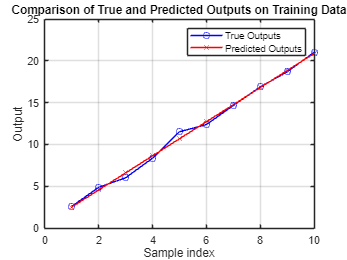


% Plotting the true and predicted outputs for the example data
figure;
plot(1:10, y_example, 'bo-', 1:10, evalModel(model_estimated, X_example), 'rx-');
xlabel('Sample index');
ylabel('Output');
legend('True Outputs', 'Predicted Outputs');
title('Comparison of True and Predicted Outputs on Training Data');
grid on;

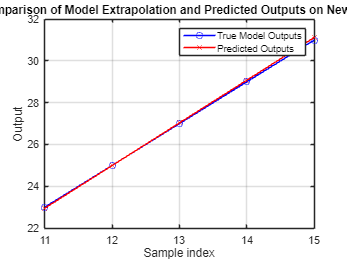


% Plotting the true model continuation and predicted outputs for the new data
y_true_new = X_new * theta_example; % True outputs for the new data based on the true model
figure;
plot(11:15, y_true_new, 'bo-', 11:15, y_pred, 'rx-');
xlabel('Sample index');
ylabel('Output');
legend('True Model Outputs', 'Predicted Outputs');
title('Comparison of Model Extrapolation and Predicted Outputs on New Data');
grid on;

# Part c)                                                                              *****Testing The Function*****

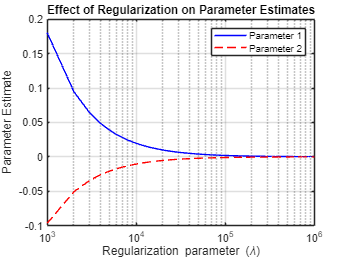

%impact of regularization on parameter estimation in LR.  Lambda acts as a penalty term 
% that controls the complexity of the model by shrinking the parameter estimates towards zero to prevent overfitting
clear; 

% range for the regularization parameter lambda
lambda_values = 0:1000:1e6; % From 0 -> 10^6
num_lambdas = length(lambda_values);

% Initialize arrays to store the estimates
theta_estimates = zeros(num_lambdas, 2); % for two parameters in the model

% true parameters and generate dataset
N = 100;
X = [ones(N, 1), randn(N, 1)]; % Design matrix with intercept
theta_true = [2; -1]; % True params
y = X * theta_true + randn(N, 1) * 0.1; % Generating outputs with noise

% Loop over lambda values and estim params
for i = 1:num_lambdas
    lambda = lambda_values(i);
    m = LinRegressRegul(X, y, lambda);
    theta_estimates(i, :) = m.theta;
end

% Plotting
figure;
semilogx(lambda_values, theta_estimates(:, 1), 'b-', 'DisplayName', 'Parameter 1');
hold on;
semilogx(lambda_values, theta_estimates(:, 2), 'r--', 'DisplayName', 'Parameter 2');
xlabel('Regularization parameter (\lambda)');
ylabel('Parameter Estimate');
legend('show');
title('Effect of Regularization on Parameter Estimates');
grid on;

# Part d)                                                                             *****Testing The Function*****

% original regressors and the degree of the polynomial
x = [2 3; 4 5];
n = 3;

% new regressor matrix for polynomial fitting
[x2,allpot] = poly_x2(x,n);

disp(x2);

     1     2     3     4     6     9     8    12    18    27
     1     4     5    16    20    25    64    80   100   125



# Part e)                                                                             *****Testing The Function*****

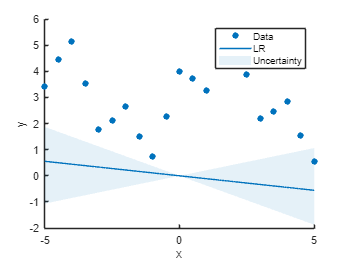

clear;
% Estimation data
x=(-5:0.5:5)';

% linear function plus noise
y=3+1.5*sin(x)+real((-1).^x);

m=LinRegress(x,y);
poly = polyfit(x,y,0,3);
knn = knnRegress(x,y,3);

x2=(-5:0.1:5)';

figure;
plotModel(x,y,m);

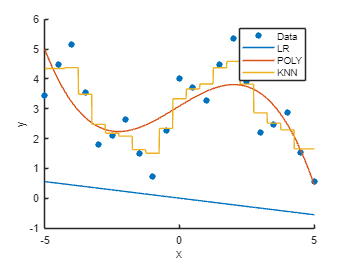


figure;
plotModel(x,y,m,poly,knn);

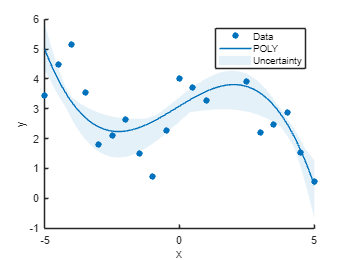


figure;
plotModel(x,y,poly);

# **TASK 2)**

# *****Testing The Function*****

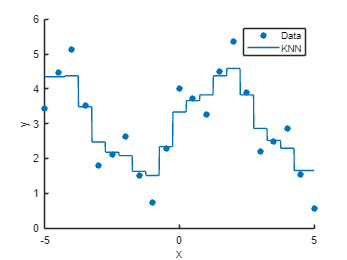

clear;
% Estim data
x = (-5:0.5:5)';
y = 3 + 1.5 * sin(x) + real((-1).^x);

% KNN regr with k=3 & k=5
knn3 = knnRegress(x, y, 3);
knn5 = knnRegress(x, y, 5);
LR = LinRegress(x,y);

figure;
plotModel(x, y, knn3);

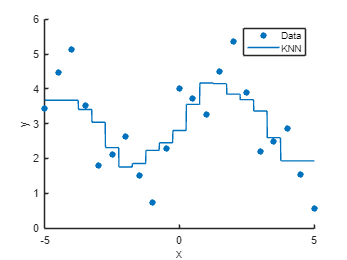

figure;
plotModel(x, y, knn5);

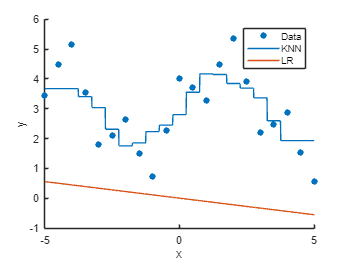

figure;
plotModel(x, y, knn5, LR);

# **TASK 3**

# **3.1.a)**

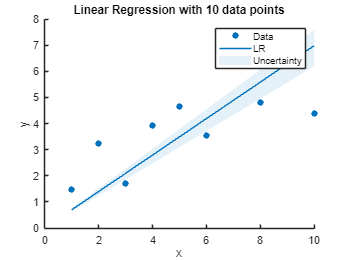

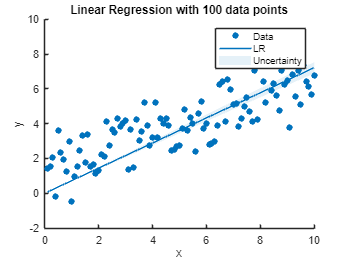

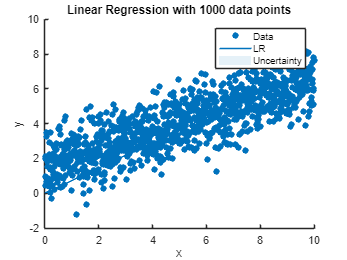

clear;
% Constants
noise_variance = 1;
sample_sizes = [10, 100, 1000];

% Store estimates and MSE for each sample size
theta_estimates = zeros(length(sample_sizes), 2); % Assuming a model with 2 parameters
mse_values = zeros(length(sample_sizes), 1);

% Loop over each sample size
for i = 1:length(sample_sizes)
    N = sample_sizes(i);
    
    % Generate dataset
    [X, y] = linearData(N, noise_variance, 0);
    
    % linear regression model
    m = LinRegress(X, y);
    theta_estimates(i, :) = m.theta';
    
    % MSE
    y_pred = evalModel(m, X);
    mse_values(i) = mean((y - y_pred).^2);
    
    % model against the data
    figure;
    plotModel(X, y, m);
    title(sprintf('Linear Regression with %d data points', N));
end


% results
disp('Theta Estimates:');

Theta Estimates:


disp(theta_estimates);

    0.6987    0.6987
    0.7214    0.7214
    0.7235    0.7235



disp('MSE Values:');

MSE Values:


disp(mse_values);

    1.8597
    1.6387
    1.6378



# **3.1.b)**

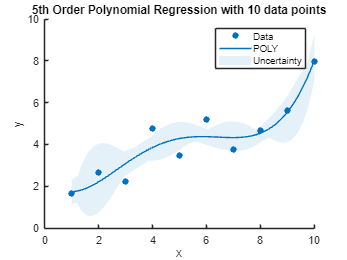

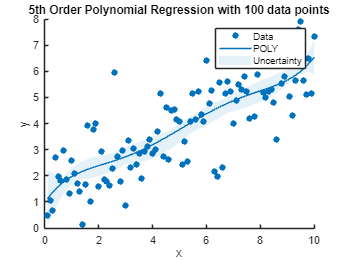

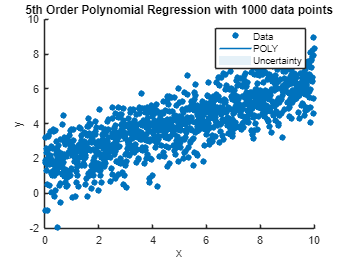

clear;
noise_variance = 1;
sample_sizes = [10, 100, 1000];
degree = 5; % polynom degree

for i = 1:length(sample_sizes)
    N = sample_sizes(i);
    
    % dataset
    [X, y] = linearData(N, noise_variance, 0);
    
    % init X_poly with a column of ones for the intercept term
    X_poly = ones(N, 1);

    % design matrix for a 5th order polynomial
    for d = 1:degree
        X_poly = [X_poly, X.^d];
    end
    
    m_poly = polyfit(X, y, 0, degree); % 0 for lambda since we're not regularizing
    
    % predictions
    y_pred_poly = evalModel(m_poly, X_poly);
    
    % MSE 
    mse_values_poly(i) = mean((y - y_pred_poly).^2);
    
    % model against the data
    figure;
    plotModel(X, y, m_poly);
    title(sprintf('5th Order Polynomial Regression with %d data points', N));
end


% MSE values
disp('MSE Values for 5th Order Polynomial Regression:');

MSE Values for 5th Order Polynomial Regression:


disp(mse_values_poly);

    0.3494    1.0710    1.0448



# **3.1.c)**

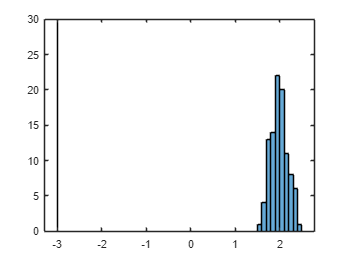

clear;
N = 100; % data points in each dataset
num_simulations = 100; % Monte Carlo simulations
noise_variance = 1; % Variance of the noise
true_parameters = [2; -3]; % True parameters (intercept and slope)

theta_estimates = zeros(num_simulations, 2); % Initialize storage for parameter estimates

% Monte Carlo Simulation for parameter estimation
for i = 1:num_simulations
    % Generate dataset with noise
    X = [ones(N, 1), (1:N)']; % Design matrix with intercept and linear term
    e = randn(N, 1) * sqrt(noise_variance); % Generate random noise
    y = X * true_parameters + e; % Generate responses with noise
    
    % Estimate parameters using custom linear regression function
    m = LinRegress(X, y); 
    
    % Store the estimated parameters
    theta_estimates(i, :) = m.theta';
end

% Plot histograms of the estimated parameters
figure;
histogram(theta_estimates(:,1), 'BinMethod', 'auto'); % Histogram for intercept estimates
hold on;
histogram(theta_estimates(:,2), 'BinMethod', 'auto'); % Histogram for slope estimates
hold off;


% Calculate and display empirical variances of the parameter estimates
empirical_variance_intercept = var(theta_estimates(:,1));
empirical_variance_slope = var(theta_estimates(:,2));
disp(['Empirical Variance of Intercept Estimates: ', num2str(empirical_variance_intercept)]);

Empirical Variance of Intercept Estimates: 0.035612


disp(['Empirical Variance of Slope Estimates: ', num2str(empirical_variance_slope)]);

Empirical Variance of Slope Estimates: 9.6539e-06


# **3.1.d)**

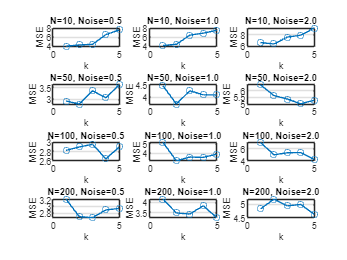

clear;
sample_sizes = [10, 50, 100, 200]; % to test
noise_variances = [0.5, 1, 2]; % noise levels to test
k_values = 1:5; % k values to try
num_simulations = 50; % no. of simulations for each setting

% Inits.
results = struct();
figure;
% Total number of plots
total_plots = length(sample_sizes) * length(noise_variances);
plot_number = 1; % Init plot counter

% Loop over sample sizes and noise variances
for N = sample_sizes
    for noise_variance = noise_variances
        
        % space for MSE values for each k
        mse_for_k = zeros(length(k_values), 1);
        
        for k = k_values
            mse_total = 0; 

            % Monte Carlo Simulations for the current setting
            for sim = 1:num_simulations
                % Generating data
                [X, y] = linearData(N, noise_variance, 0);

                % Splitting into train and validation sets
                % using a simple 50-50 split for plotting purposes
                half = floor(N / 2);
                X_train = X(1:half, :);
                y_train = y(1:half, :);
                X_val = X(half+1:end, :);
                y_val = y(half+1:end, :);

                % Trainin KNN model
                m_knn = knnRegress(X_train, y_train, k);

                % Validating KNN model
                y_pred = evalModel(m_knn, X_val);
                mse = mean((y_val - y_pred).^2);
                mse_total = mse_total + mse;
            end
            
            % average MSE for k
            mse_for_k(k) = mse_total / num_simulations;
        end
        
        % results
        results(N).(strcat('noise_', strrep(num2str(noise_variance), '.', 'p'))) = mse_for_k;

        subplot(length(sample_sizes), length(noise_variances), plot_number);
        plot(k_values, mse_for_k, '-o');
        title(sprintf('N=%d, Noise=%0.1f', N, noise_variance));
        xlabel('k');
        ylabel('MSE');
        grid on; 
        plot_number = plot_number + 1;
        
    end
end

# **3.2.a)**

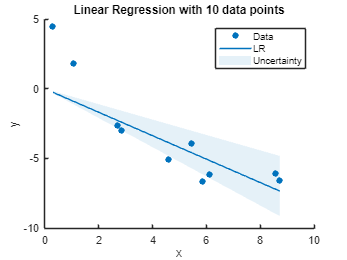

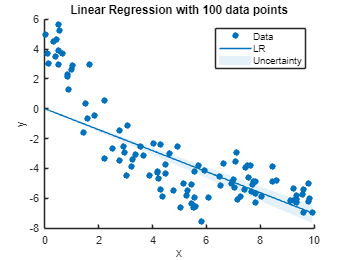

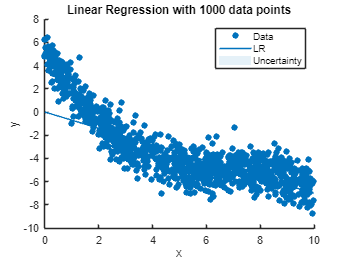

noise_variance = 1;
sample_sizes = [10, 100, 1000];

% estimates and MSE for each sample size
theta_estimates = zeros(length(sample_sizes), 2); % Assuming a model with 2 parameters
mse_values = zeros(length(sample_sizes), 1);

for i = 1:length(sample_sizes)
    N = sample_sizes(i);
    
    % Generate dataset
    [X, y] = polyData(N, noise_variance, 0);
    
    % Estimatin linear regression model
    m = LinRegress(X, y);
    
    % Store estimates
    theta_estimates(i, :) = m.theta';
    
    % MSE
    y_pred = evalModel(m, X);
    mse_values(i) = mean((y - y_pred).^2);
    
    figure;
    plotModel(X, y, m);
    title(sprintf('Linear Regression with %d data points', N));
end


% results
disp('Theta Estimates:');

Theta Estimates:


disp(theta_estimates);

   -0.8423   -0.8423
   -0.7038   -0.7038
   -0.7018   -0.7018



disp('MSE Values:');

MSE Values:


disp(mse_values);

    3.7887
    4.3821
    3.2271



# **3.2.b)**

clear;
noise_variance = 1;
N = 15; % Small dataset 
degrees = 1:10; % Polynomial degrees to try
regularization_params = [0.01, 0.1, 1, 10, 100]; % regularization strengths to compare

mse_values_poly_reg = zeros(length(degrees), length(regularization_params));
[X, y] = polyData(N, noise_variance, 0);

for i = 1:length(degrees)
    degree = degrees(i);
    
    % regularization params
    for j = 1:length(regularization_params)
        lambda = regularization_params(j);
        
        % Extending X to include polynomial terms up to degree
        X_poly = [ones(N, 1)]; % column for intercept
        for d = 1:degree
            X_poly = [X_poly, X.^d];
        end
        
        m_poly_reg = LinRegressRegul(X_poly, y, lambda);
        y_pred_poly_reg = evalModel(m_poly_reg, X_poly);
        mse_values_poly_reg(i, j) = mean((y - y_pred_poly_reg).^2);
    end
end

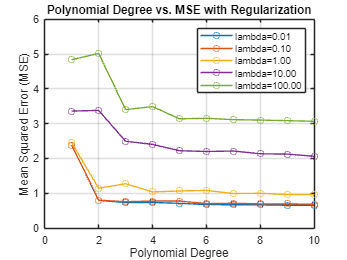


figure;
for j = 1:length(regularization_params)
    plot(degrees, mse_values_poly_reg(:, j), '-o', 'DisplayName', sprintf('lambda=%.2f', regularization_params(j)));
    hold on;
end
title('Polynomial Degree vs. MSE with Regularization');
xlabel('Polynomial Degree');
ylabel('Mean Squared Error (MSE)');
legend('show');
grid on;
hold off;

# **3.2.c)**

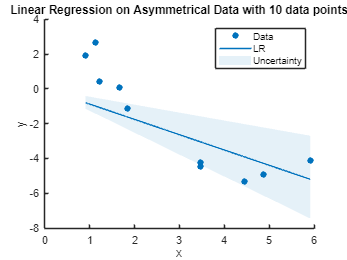

%with asymetrical data -> increased error or biased
clear;
noise_variance = 1;
N = 10; 

% asymmetrical dataset using polyData with a third argument set to '1'
[X, y] = polyData(N, noise_variance, 1);
m_linear = LinRegress(X, y);
y_pred_linear = evalModel(m_linear, X);
mse_linear = mean((y - y_pred_linear).^2);

% model against the data
figure;
plotModel(X, y, m_linear);
title(sprintf('Linear Regression on Asymmetrical Data with %d data points', N));


% results
disp('Theta Estimates for Asymmetrical Data:');

Theta Estimates for Asymmetrical Data:


disp(m_linear.theta');

   -0.8796



disp('MSE for Asymmetrical Data:');

MSE for Asymmetrical Data:


disp(mse_linear);

    3.2456



# **3.2.d)**

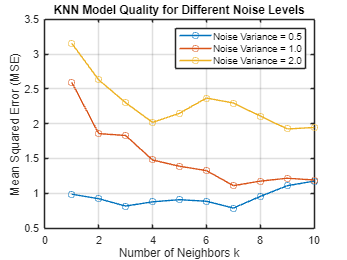

clear;
%Model Quality for Different Noise Levels. 
sample_size = 100; % fixed sample size for this one
noise_variances = [0.5, 1, 2]; 
k_values = 1:10; % k values to test

% Preallocate space for storing MSE values
mse_for_k = zeros(length(k_values), length(noise_variances));

% noise variances lopp
for j = 1:length(noise_variances)
    noise_variance = noise_variances(j);

    % Generate dataset
    [X, y] = polyData(sample_size, noise_variance, 0);

    % Splitting into training and testing datasets
    % using a 70-30 split for plotting purposes
    idx = randperm(sample_size);
    train_idx = idx(1:round(0.7 * sample_size));
    test_idx = idx(round(0.7 * sample_size) + 1:end);
    X_train = X(train_idx, :);
    y_train = y(train_idx);
    X_test = X(test_idx, :);
    y_test = y(test_idx);

    % k values
    for i = 1:length(k_values)
        k = k_values(i);

        % Training KNN model
        m_knn = knnRegress(X_train, y_train, k);

        % Validating KNN model
        y_pred = evalModel(m_knn, X_test);
        mse_for_k(i, j) = mean((y_test - y_pred).^2);
    end
end

% MSE vs k for each noise level
figure;
for j = 1:length(noise_variances)
    plot(k_values, mse_for_k(:, j), '-o', 'DisplayName', sprintf('Noise Variance = %.1f', noise_variances(j)));
    hold on;
end
xlabel('Number of Neighbors k');
ylabel('Mean Squared Error (MSE)');
title('KNN Model Quality for Different Noise Levels');
legend('show');
grid on;

# **3.3.a)**

clear;
%how the complexity of polynomial regression models 
% (varied through polynomial degrees) interacts with 
% different dataset sizes to affect model performance
noise_variance = 0.2;
small_N = 50;
large_N = 1000;
degrees = 1:10; % polynom degrees to try

[X_small, y_small] = chirpData(small_N, noise_variance); % small dataset

% Fit models and calculate MSE for the small dataset
mse_small = zeros(length(degrees), 1);
for i = 1:length(degrees)
    % polynomial features
    X_poly = poly_x2(X_small, degrees(i));
    % Fit polynomial regress
    model = polyfit(X_small, y_small, 0, degrees(i)); 
    % predictions and MSE
    y_pred = evalModel(model, X_poly); 
    mse_small(i) = mean((y_small - y_pred).^2);
end

% smallest MSE for the small dataset + best degree
[~, best_degree_small] = min(mse_small);

% for the large dataset
[X_large, y_large] = chirpData(large_N, noise_variance);
mse_large = zeros(length(degrees), 1);
for i = 1:length(degrees)
    X_poly = poly_x2(X_large, degrees(i));
    model = polyfit(X_large, y_large, 0, degrees(i)); 
    y_pred = evalModel(model, X_poly); 
    mse_large(i) = mean((y_large - y_pred).^2);
end

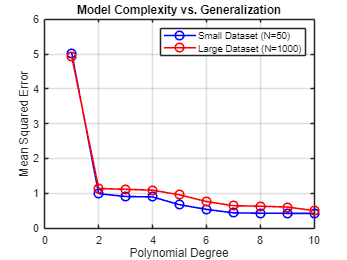


% smallest MSE for the large dataset + best degree
[~, best_degree_large] = min(mse_large);
% Plot MSE against polynomial degree
figure;
plot(degrees, mse_small, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 8);
hold on;
plot(degrees, mse_large, 'r-o', 'LineWidth', 1.5, 'MarkerSize', 8);
hold off;
xlabel('Polynomial Degree');
ylabel('Mean Squared Error');
title('Model Complexity vs. Generalization');
legend(['Small Dataset (N=', num2str(small_N), ')'], ['Large Dataset (N=', num2str(large_N), ')']);
grid on;

fprintf('Best degree for small dataset (%d data points): %d with an MSE of %.4f\n', small_N, best_degree_small, mse_small(best_degree_small));

Best degree for small dataset (50 data points): 10 with an MSE of 0.4211


fprintf('Best degree for large dataset (%d data points): %d with an MSE of %.4f\n', large_N, best_degree_large, mse_large(best_degree_large));

Best degree for large dataset (1000 data points): 10 with an MSE of 0.4999


# **3.3.b)**

clear;
noise_variance = 0.1;
N = 50; % data points
degree = 10; % High-degree polynomial to try
regularization_params = [0.01, 0.1, 1, 10, 100]; % Regularization strengths

% dataset
[X, y] = chirpData(N, noise_variance);

% arrays for storing results
mse_values = zeros(length(regularization_params), 1);
models = cell(length(regularization_params), 1);

% regularization parameters to fit models and find MSE
for i = 1:length(regularization_params)
    lambda = regularization_params(i);
    
    % polynomial features up to the spec. degree
    [X_poly, ~] = poly_x2(X, degree);
    
    % Fit polynomial regress with regularization
    models{i} = polyfit(X, y, lambda, degree);
    
    % predictions using the polynomial features and MSE
    y_pred = evalModel(models{i}, X_poly);
    mse_values(i) = mean((y - y_pred).^2);
end


% regularization parameter with the smallest MSE
[best_mse, best_idx] = min(mse_values);
best_lambda = regularization_params(best_idx);
best_model = models{best_idx};
fprintf('The best regularization parameter is %f with an MSE of %.4f\n', best_lambda, best_mse);

The best regularization parameter is 0.010000 with an MSE of 0.4579


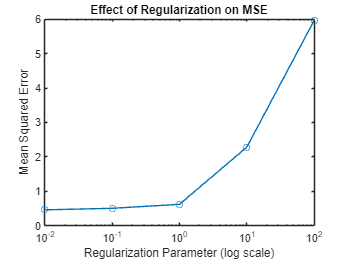

figure;
semilogx(regularization_params, mse_values, '-o');
title('Effect of Regularization on MSE');
xlabel('Regularization Parameter (log scale)');
ylabel('Mean Squared Error');

# **3.3.c)**

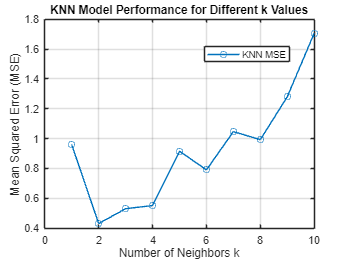

clear;
noise_variance = 0.2; 
N = 50; 
k_values = 1:10; 
[X, y] = chirpData(N, noise_variance);

% training and validation sets
idx = randperm(N);
train_idx = idx(1:floor(0.7 * N)); % 70% for training
val_idx = idx(floor(0.7 * N) + 1:end); % 30% for validation
X_train = X(train_idx);
y_train = y(train_idx);
X_val = X(val_idx);
y_val = y(val_idx);

mse_values_knn = zeros(length(k_values), 1);
% KNN models for different k values
for i = 1:length(k_values)
    k = k_values(i);
    
    % Training
    m_knn = knnRegress(X_train, y_train, k);
    
    % Validating
    y_pred_knn = evalModel(m_knn, X_val);
    mse_values_knn(i) = mean((y_val - y_pred_knn).^2);
end

% MSE vs. k
figure;
plot(k_values, mse_values_knn, '-o');
xlabel('Number of Neighbors k');
ylabel('Mean Squared Error (MSE)');
title('KNN Model Performance for Different k Values');
legend('KNN MSE', 'Location', 'best');
grid on;


% best k based on the lowest MSE
[best_mse, best_k_idx] = min(mse_values_knn);
best_k = k_values(best_k_idx);
fprintf('Best k by MSE: %d with an MSE of %.2f\n', best_k, best_mse);

Best k by MSE: 2 with an MSE of 0.43


# **TASK 4)**

# **4.1.a)**

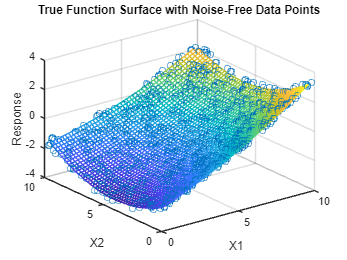

% generating and visualizing a two-dimensional noise-free dataset
clear ;
% Generate noise-free data
N = 1000; % number of data points for visualization
[X, y] = twoDimData1(N, 0); 

% Visualize the true function
[xq, yq] = meshgrid(0:0.2:10, 0:0.2:10); % grid for the x and y axis
vq = griddata(X(:, 1), X(:, 2), y, xq, yq); % Interpolate the function values on the grid points
mesh(xq, yq, vq); % Plotting the function as a surface

hold on;
plot3(X(:, 1), X(:, 2), y, 'o'); % Overlay noise-free data points
xlabel('X1');
ylabel('X2');
zlabel('Response');
title('True Function Surface with Noise-Free Data Points');
hold off;

# **4.1.b)**

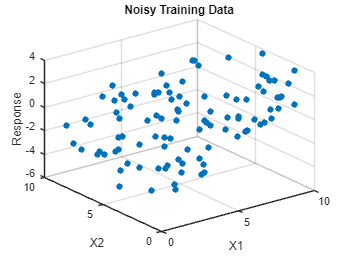

%extending the previous setup by 
%introducing noise into the training and validation datasets
noise_variance = 1; % Specified noise level
train_N = 100; % Number of training data points
val_N = 1000; % Number of validation data points for evaluation

% Generate noisy training data
[X_train, y_train] = twoDimData1(train_N, noise_variance);

% Generate a noisy validation set
[X_val, y_val] = twoDimData1(val_N, noise_variance);

% Optionally visualize the noisy training data
figure;
scatter3(X_train(:, 1), X_train(:, 2), y_train, 'filled');
hold on;
title('Noisy Training Data');
xlabel('X1');
ylabel('X2');
zlabel('Response');
grid on;

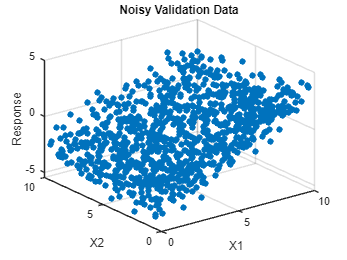


% Optionally visualize the noisy validation data
figure;
scatter3(X_val(:, 1), X_val(:, 2), y_val, 'filled');
title('Noisy Validation Data');
xlabel('X1');
ylabel('X2');
zlabel('Response');
grid on;

# **4.1.c)**

%fitting a linear regression model to the noisy training data and 
%evaluating its performance on the noisy validation data

% fit lr to the training data
linear_model = LinRegress(X_train, y_train);

% Evaluate the linear model on the validation set
y_pred_val_linear = evalModel(linear_model, X_val);
mse_val_linear = mean((y_val - y_pred_val_linear).^2);

% Output the MSE for the linear regression model
fprintf('MSE for Linear Regression: %.4f\n', mse_val_linear);

MSE for Linear Regression: 2.7507


# **4.1.d)**

%assessing polynomial regression models of various 
% degrees to determine which degree provides the best fit for the data

% Define polynomial degrees to test
poly_degrees = 2:5;

% Preallocate array for storing MSE values
mse_values_poly = zeros(length(poly_degrees), 1);

% Fit polynomial models and calculate MSE
for i = 1:length(poly_degrees)
    degree = poly_degrees(i);
    
    % Generate polynomial features
    [X_poly_train, ~] = poly_x2(X_train, degree);
    [X_poly_val, ~] = poly_x2(X_val, degree);
    
    % Fit polynomial regression model
    poly_model = polyfit(X_train, y_train, 0, degree); % No regularization
    
    % Evaluate the polynomial model on the validation set
    y_pred_val_poly = evalModel(poly_model, X_poly_val);
    mse_values_poly(i) = mean((y_val - y_pred_val_poly).^2);
end

% Output the MSE for each polynomial degree
for i = 1:length(poly_degrees)
    fprintf('MSE for Polynomial Degree %d: %.4f\n', poly_degrees(i), mse_values_poly(i));
end

MSE for Polynomial Degree 2: 1.1600
MSE for Polynomial Degree 3: 1.1933
MSE for Polynomial Degree 4: 1.1827
MSE for Polynomial Degree 5: 1.3733



[best_mse_poly, best_degree_idx] = min(mse_values_poly);
best_degree_poly = poly_degrees(best_degree_idx);

% Output the best degree and its MSE
fprintf('Best degree for Polynomial Regression: %d with MSE: %.4f\n', best_degree_poly, best_mse_poly);

Best degree for Polynomial Regression: 2 with MSE: 1.1600


# **4.1.e)**

%comparing poly and best found knn

k_values = 1:20; % Range of k values to test for KNN
mse_values_knn = zeros(length(k_values), 1);
for i = 1:length(k_values)
    k = k_values(i);
    knn_model = knnRegress(X_train, y_train, k);
    y_pred_knn = evalModel(knn_model, X_val);
    mse_values_knn(i) = mean((y_val - y_pred_knn).^2);
end

% k value with smallest MSE
[best_mse_knn, best_k_idx] = min(mse_values_knn);
best_k = k_values(best_k_idx);
fprintf('Best k for KNN: %d with MSE: %.4f\n', best_k, best_mse_knn);

Best k for KNN: 9 with MSE: 1.3789



if best_mse_knn < best_mse_poly
    fprintf('KNN model is better than the polynomial model with MSE: %.4f\n', best_mse_knn);
else
    fprintf('Polynomial model is better than the KNN model with MSE: %.4f\n', best_mse_poly);
end

Polynomial model is better than the KNN model with MSE: 1.1600


# **4.2.a)**

%number of regressors required for linear and polynomial 
% (up to degree 3) regression models in a 10-dimensional dataset

clearvars -except best_mse_poly;
num_dimensions = 10;

% regressors for linear regression
num_regressors_linear = num_dimensions + 1; % Including the intercept
num_regressors_poly = 1; % Starting with the intercept term

% Linear terms
num_regressors_poly = num_regressors_poly + num_dimensions;

% Quadratic terms (squared and cross-product terms)
num_regressors_poly = num_regressors_poly + num_dimensions + nchoosek(num_dimensions, 2);

% Cubic terms (cubed, squared-cross-product, and cross-product of three different features)
num_regressors_poly = num_regressors_poly + num_dimensions + (num_dimensions * (num_dimensions - 1)) + nchoosek(num_dimensions, 3);

fprintf('Number of regressors for linear regression: %d\n', num_regressors_linear);

Number of regressors for linear regression: 11


fprintf('Number of regressors for polynomial regression up to degree 3: %d\n', num_regressors_poly);

Number of regressors for polynomial regression up to degree 3: 286


# **4.2.b)**

%Generates noisy training and validation datasets for subsequent model evaluations

noise_variance = 1; 
train_N = 1000; % training data points
val_N = 10000; % validation data points

% noisy training data
[X_train, y_train] = tenDimData(train_N, noise_variance);

% noisy validation data
[X_val, y_val] = tenDimData(val_N, noise_variance);

# **4.2.c)**

%Fits a linear regression model to the training data and 
% evaluates it on the validation dataset.


% Fitting linear regress to training data
linear_model = LinRegress(X_train, y_train);

% Evaluatiion
y_pred_val_linear = evalModel(linear_model, X_val);
mse_val_linear = mean((y_val - y_pred_val_linear).^2);

fprintf('MSE for Linear Regression on Validation Set: %.4f\n', mse_val_linear);

MSE for Linear Regression on Validation Set: 1.2507


# **4.2.d)**

%Extends the model evaluation to polynomial regression, considering up to the third degree.


% training and validation data to polynom of degree 3
[X_poly_train, ~] = poly_x2(X_train, 3);
[X_poly_val, ~] = poly_x2(X_val, 3);

% Fit polynomial regression model to the training data
poly_model_degree_3 = LinRegress(X_poly_train, y_train);

% number of regressors matches the calculated number
assert(size(X_poly_train, 2) == num_regressors_poly, 'Number of regressors does not match the calculation.');

% Evaluatiion
y_pred_val_poly = evalModel(poly_model_degree_3, X_poly_val);
mse_val_poly = mean((y_val - y_pred_val_poly).^2);

fprintf('MSE for Polynomial Regression (degree 3) on Validation Set: %.4f\n', mse_val_poly);

MSE for Polynomial Regression (degree 3) on Validation Set: 1.4321


# **4.2.e)**

%Investigates the effect of regularization on polynomial regression 
% to mitigate potential overfitting


regularization_lambdas = [0.001, 0.01, 0.1, 1, 10, 20, 30, 40, 60, 80, 100];
mse_values_regul = zeros(length(regularization_lambdas), 1);

for i = 1:length(regularization_lambdas)
    lambda = regularization_lambdas(i);
    
    % Fit with regularization
    poly_model_regul = LinRegressRegul(X_poly_train, y_train, lambda);
    
    % Evaluation
    y_pred_val_regul = evalModel(poly_model_regul, X_poly_val);
    mse_values_regul(i) = mean((y_val - y_pred_val_regul).^2);
end

% Find the regularization strength with the smallest MSE
[best_mse_regul, best_lambda_idx] = min(mse_values_regul);
best_lambda = regularization_lambdas(best_lambda_idx);

fprintf('Best regularization lambda for Polynomial Regression: %f with MSE: %.4f\n', best_lambda, best_mse_regul);

Best regularization lambda for Polynomial Regression: 20.000000 with MSE: 1.0474


# **4.2.f)**

%Compares the performance of KNN models across a range of k values 
%and contrasts the best KNN model with the best polynomial model.

% Range of k values to test
k_values = 1:20;

% Preallocate array for MSE values of KNN models
mse_values_knn = zeros(length(k_values), 1);

% Loop over k values to train KNN models and calculate MSE on validation data
for i = 1:length(k_values)
    k = k_values(i);
    
    % Train KNN model
    knn_model = knnRegress(X_train, y_train, k);
    
    % Evaluate the KNN model on the validation set
    y_pred_knn = evalModel(knn_model, X_val);
    mse_values_knn(i) = mean((y_val - y_pred_knn).^2);
end

% Find the best k value and corresponding MSE
[best_mse_knn, best_k_idx] = min(mse_values_knn);
best_k = k_values(best_k_idx);

fprintf('Best k for KNN: %d with MSE: %.4f\n', best_k, best_mse_knn);

Best k for KNN: 18 with MSE: 1.1823



% Compare to the best polynomial model's MSE
% Assume you stored the best polynomial model's MSE in `best_mse_poly`
if best_mse_knn < best_mse_poly
    fprintf('KNN model (k=%d) is better than the best polynomial model with MSE: %.4f\n', best_k, best_mse_knn);
else
    fprintf('Best polynomial model is better than KNN model (k=%d) with MSE: %.4f\n', best_k, best_mse_poly);
end

Best polynomial model is better than KNN model (k=18) with MSE: 1.1600


# **Functions Developed:**

function m = LinRegress(x,y)
%used to estimate the model parameters from the design matrix X and output vector y
    [Ny,ny] = size(y);
    [Nx,nx] = size(x);
    m.model = 'LR'; % linear regr.model
    
    if Nx == Ny % Test that the number of data is the same in x and y ->so each pred has a correspo. value
        
        m.theta = (x'*x)\(x'*y); % LS estimation of regress coeffs
           
        if ny == 1 % calculate uncertainty only in the case that there is one output
            %If the model has only one output, calculate the residuals and 
            % use these to estimate the variance of the error term

            % Estimating the variance of the error term
            residuals = y - x * m.theta; %error terms for each observation, indicating how much the model's 
                                         % prediction deviates from the actual observed value
                                         
            sigma2 = (residuals' * residuals) / (Ny - nx); % according to 4.13 the residuals should be
                                        
            % variance of the parameters
            m.variance = sigma2 * inv(x' * x); % variance of theta_hat
            
        else
           m.variance = 'None';
        end
    else
        m.theta = NaN;
        m.model = 'None';
        m.variance = 'None';
        disp('Dimension mismatch for output and regressor.')
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function y_pred = evalModel(m, X)
    if strcmp(m.model, 'LR') || strcmp(m.model, 'POLY') % Linear or Polynomial models

        y_pred = X * m.theta(:);

    elseif strcmp(m.model, 'knn') % KNN model
        y_pred = zeros(size(X, 1), 1); % Initializing the output

        for i = 1:size(X, 1)
            % For each new input, calculate distances from training data, 
            % find the knn, and average their outputs to make a prediction
            distances = sqrt(sum(bsxfun(@minus, m.x, X(i)).^2, 2));
            [~, sortedIndices] = sort(distances);
            closestIndices = sortedIndices(1:m.k);
            y_pred(i) = mean(m.y(closestIndices));
        end

    else
        error('Unknown model type');
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function m = LinRegressRegul(x, y, lambda)
%extending linregress to prevent overfitting
%by appending scaled identity matrices and zero vectors, respectively 
% This effectively adds a regularization term (λθ^2) to the least squares loss function

    % Appending extra rows to x and y for regularization
    x2 = [x; sqrt(lambda)*eye(size(x,2))];
    y2 = [y; zeros(size(x,2), 1)];
    
    % LinRegress function on the updated x2 and y2
    m = LinRegress(x2, y2);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [x2, allpot] = poly_x2(x, n)
% expanding the feature space to include polynomial terms, 
% which allows the linear model to fit more complex patterns
    [Nx, nx] = size(x);

    % Generating all possible combinations of exponents for monomials
    if nx == 1
        % If only one regressor simply generating the powers of it
        allpot = (0:n)';
    else
        % combinations for multiple regressors
        allpot = [];
        for total_degree = 0:n
            % Generatin & appending combinations for the current total degree
            allpot = [allpot; flipud(generateCombinations(nx, total_degree))];
        end
    end
    
    nmon = size(allpot, 1); % No. of monomials is the number of rows in allpot
    
    % Preparing empty matrix for the extended regressor matrix
    x2 = ones(Nx, nmon);
    
    % Fill in the x2 matrix
    for ii = 1:nmon
        % Calculating each monomial using one row of allpot and x
        for var_idx = 1:nx
            x2(:, ii) = x2(:, ii) .* (x(:, var_idx) .^ allpot(ii, var_idx));
        end
    end
end

function combinations = generateCombinations(num_vars, total_degree)
%  a recursive helper function for poly_x2 to generate all combinations of exponents 
% for a given total degree across multiple variables.
    % all combinations of exponents for num_vars summing to total_degree
    if num_vars == 1
        combinations = total_degree;
    else
        combinations = [];
        for i = 0:total_degree
            % Recursively generating combinations for one less variable
            sub_combinations = generateCombinations(num_vars - 1, total_degree - i);
            % Pre-apending the current exponent to each combination
            combinations = [combinations; [i * ones(size(sub_combinations, 1), 1), sub_combinations]];
        end
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function m = polyfit(x, y, lambda, n)
    % extended regressor matrix -> lambda to ->reg. param to control degree
    % of shrinkage
    [x2, allpot] = poly_x2(x, n);

    % regularized linear regression using the extended matrix
    m = LinRegressRegul(x2, y, lambda);
    m.n = n;
    m.model = 'POLY'; % polynomial regr.model
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function plotModel(x, y, varargin)

    scatter(x, y, 'filled', 'DisplayName', 'Data'); % for data points
    hold on;
    
    % Colors for plotting each model
    colors = lines(max(length(varargin), 1));

    %  for smooth plots
    x2 = linspace(min(x), max(x), 1000)';  % could have been x2=(-5:0.1:5)';  
                                           % according to Test_plotModel
                                           

    for i = 1:length(varargin) %iterating over each model
        m = varargin{i};

        % Check-point for the model type
        if strcmp(m.model, 'knn')
            % KNN model
            y_pred = evalModel(m, x2); % Directly use x2 for KNN
            plot(x2, y_pred, 'Color', colors(i,:), 'DisplayName', 'KNN');
        elseif strcmp(m.model, 'POLY')
            % Polynomial model
            X_design = poly_x2(x2, m.n);
            y_pred = evalModel(m, X_design);
            plot(x2, y_pred, 'Color', colors(i,:), 'DisplayName', 'POLY');
        else
            % Linear model
            X_design = [ones(size(x2, 1), 1), x2];
            y_pred = evalModel(m, X_design);
            % excluding the intercept (1st.col) 
            [yr, yc] = size(y_pred);
            if yc >= 2
                y_pred = y_pred(:,2:end);
                plot(x2, y_pred, 'Color', colors(i,:), 'DisplayName', 'LR');
            else
                plot(x2, y_pred, 'Color', colors(i,:), 'DisplayName', 'LR');
            end

        end


        % uncertainty for a single model with variance information
        if length(varargin) == 1 && isfield(varargin{1}, 'variance') && ...
                size(varargin{1}.variance, 1) == size(varargin{1}.variance, 2)
   
            m = varargin{1};
    
            % Generating the design matrix depending on the model type
            if strcmp(m.model, 'LR')
                X_design = [ones(size(x2, 1), 1), x2];  % Adding intercept for linear regression
            elseif strcmp(m.model, 'POLY')
                X_design = poly_x2(x2, m.n);  % includes the intercept in the design
            end
%%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%%  
%%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%%  
            num_samples = 10;  %%%%%%%%%%%%%% ADJUST sampling size %%%%%%%%%%%%%%
%%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%%  
%%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%%  

            y_sims = zeros(length(x2), num_samples);

            % Generatin outputs for each sample using Monte Carlo simu.
            for i = 1:num_samples
                % Sample from the parameter distribution
                theta_sample = mvnrnd(m.theta, m.variance); % Monte Carlo simulations rely on repeated random sampling to approximate a statistical measurement. 
%mvnrnd function is used to draw random samples from a multivariate normal distribution defined 
% by the estimated parameters (theta) and their variance matrix. used to generate all possible 
% terms up to the specified polynomial degree   

                % Since random numbers are involved, the output can vary with each run 
                % unless the random number generator seed is fixed.
                % in case consistent plots are needed we can use: 
                % rng(123); % Sets the seed of the random number generator for reproducibility
                
        
                % checkin the model with the sampled params
                if strcmp(m.model, 'POLY')
                    y_sims(:, i) = evalModel(struct('theta', theta_sample, 'model', m.model), X_design);
                else
                    % x2 can be passed directly
                    y_sims(:, i) = evalModel(struct('theta', theta_sample, 'model', m.model), x2);
                end
            end

            % the 2.5th and 97.5th percentiles -> to achieve a 95% confidence  
            y_lower = prctile(y_sims, 2.5, 2);
            y_upper = prctile(y_sims, 97.5, 2);
%computes the 2.5th percentile (lower bound) of the predicted values for each point in x2 
% across all simulations, and prctile(y_sims, 97.5, 2) computes the 97.5th percentile (upper bound). 
% The second argument in prctile specifies the dimension along which the percentiles are calculated, 
%ensuring the function evaluates across the simulations rather than across the different points in x2.
            % Plotting 
            fill([x2; flipud(x2)], [y_upper; flipud(y_lower)], ...
                colors(1,:), 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Uncertainty');
        end

        
    end

    xlabel('x');
    ylabel('y');
    legend show;
    hold off;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function m = knnRegress(x, y, k)
    % KNN model
    m.x = x;
    m.y = y;
    m.k = k;
    m.model = 'knn'; 
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%